
n=1.2

n = 1.2000

D=0.5805

D = 0.5805


R=7.5

R = 7.5000

L=2.6195e-5

L = 2.6195e-05

C=100e-6

C = 1.0000e-04


Dp=1-D

Dp = 0.4195


Zn=(-Dp^2*R/(n^2*D^2)) *...
    tf([ ...Numerator
    -D*n^2*L/(Dp^2*R) ...s
    ,1], ...
    [ ...Denumerator
    1])

Zn =
 
  4.512e-05 s - 2.72
 
Continuous-time transfer function.




Zd = (Dp^2*R/(n^2*D^2)) * ... Constant
    tf([ ...Numerator
    n^2*L*C/Dp^2, ...s^2
    n^2*L/(Dp^2*R), ...s
    1], ...
    [ ...Denumerator
    R*C, ... s
    1])

Zd =
 
  5.83e-08 s^2 + 7.773e-05 s + 2.72
  ---------------------------------
            0.00075 s + 1
 
Continuous-time transfer function.



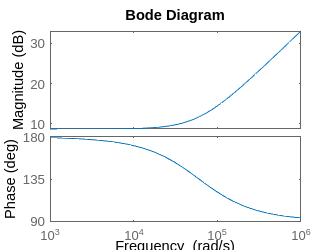





bodeplot(Zn)

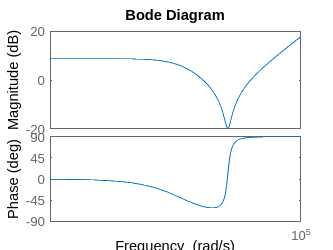

bodeplot(Zd)

Kc=9 %Factor between first and second stage caps

Kc = 9



zpk(Zn)

ans =
 
  4.5125e-05 (s-6.028e04)
 
Continuous-time zero/pole/gain model.



zpk(Zd)

ans =
 
  7.7735e-05 (s^2 + 1333s + 4.665e07)
  -----------------------------------
               (s+1333)
 
Continuous-time zero/pole/gain model.






dcgain(Zd)

ans = 2.7199

dcgain(Zn)

ans = -2.7199


[z,p,k]=zpkdata(Zd)

z = 1×1 cell array
    {2×1 double}


p = 1×1 cell array
    {[-1.3333e+03]}


k = 7.7735e-05


z{1}

ans = 	1.0e+03 *

  -0.6667 + 6.7977i
  -0.6667 - 6.7977i


p{1}

ans = -1.3333e+03


f0=min(arrayfun(@abs,z{1}))

f0 = 6.8303e+03

f1=min(arrayfun(@abs,p{1}))

f1 = 1.3333e+03


f0/(2*pi)

ans = 1.0871e+03

f1/(2*pi)

ans = 212.2066


zi=min(abs(evalfr(Zn,i*f0)),...
       abs(evalfr(Zd,i*f0)))

zi = 0.1017


20*log10(zi)

ans = -19.8514


evalfr(Zn,1)

ans = -2.7199


3/(f0*zi*Kc)

ans = 4.7974e-04


c=3/(f0*zi*Kc)

c = 4.7974e-04

c=5e-4

c = 5.0000e-04


l=1/(c*f1^2*(Kc+1)^2)

l = 1.1250e-05


l=12e-6

l = 1.2000e-05


r=0.3

r = 0.3000




p = @(x,y)1/((1/x)+(1/y));



s = tf('s');

Zo=p( ...
    s*l+p( ...
            r, ...
            p( ...
                Kc*l*s, ...
                1/(s*c) ...
              ) ...
          ) ...
    ,1/(Kc*c*s))

Zo =
 
            6.48e-13 s^3 + 4.32e-09 s^2 + 0.00012 s
  ------------------------------------------------------------
  2.916e-15 s^4 + 1.944e-11 s^3 + 5.94e-07 s^2 + 0.00036 s + 1
 
Continuous-time transfer function.





zpk(Zo,'v')

ans =
 
          222.22 s (s^2 + 6667s + 1.852e08)
  --------------------------------------------------
  (s^2 + 568.9s + 1.728e06) (s^2 + 6098s + 1.985e08)
 
Continuous-time zero/pole/gain model.



[z, p, k]=zpkdata(Zo)

z = 1×1 cell array
    {3×1 double}


p = 1×1 cell array
    {4×1 double}


k = 222.2222


z{1}

ans = 	1.0e+04 *

   0.0000 + 0.0000i
  -0.3333 + 1.3194i
  -0.3333 - 1.3194i


p{1}

ans = 	1.0e+04 *

  -0.3049 + 1.3755i
  -0.3049 - 1.3755i
  -0.0284 + 0.1283i
  -0.0284 - 0.1283i


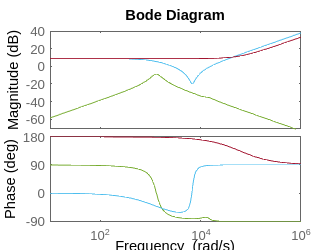






figure(1)
hold on
bode(Zo)
bode(Zd)
bode(Zn)
hold off


l*9

ans = 1.0800e-04

c*9

ans = 0.0045